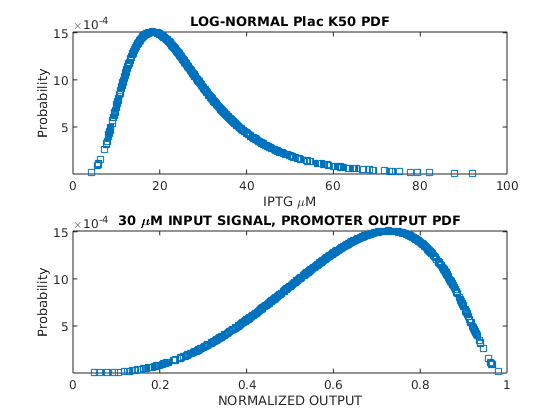

FS = 20;

rsamples  = 1000;

% distArray = 1e4;
% 
% for i=1:length(distArray)
%     xmu = distArray(i);  
%     xs2 = 0.05*xmu*xmu;%use square of mean for variance
% %     %conversions from target to log-normal mean,variance:
%     lnmu = log(xmu/sqrt(1 + xs2/(xmu*xmu)));
%     lns2 = log(1 + xs2/(xmu*xmu));
%     pd = makedist('Lognormal','mu',lnmu,'sigma',lns2);
%     r = random(pd,rsamples,1); % generate numbers from the distribution
%     ix = linspace(min(r),max(r)); % to scale the graph
%     y = pdf(pd, ix);
%     plot(ix,y); hold on;
% end
% hold off;

figure;
    xmu = 0.5;
%     xs = 0.2;
    xs = 0.4;  %CHANGED TO LARGER STD.DEV. FOR REALISM IN NEW PROJECT
    xs2 = xs^2;
    xr = xs/xmu;
    
%     xmu = 1e4;
%     xs2 = (xmu*xr)^2;
%     
% %     %conversions from target to log-normal mean,variance:
%     lnmu = log(xmu/sqrt(1 + xs2/(xmu*xmu)));
%     lns2 = log(1 + xs2/(xmu*xmu));
%     pd = makedist('Lognormal','mu',lnmu,'sigma',lns2);
%     r = random(pd,rsamples,1); % generate numbers from the distribution
%     ix = linspace(min(r),max(r)); % to scale the graph
%     y = pdf(pd, ix);
%     plot(ix,y); 

%==============================================
%  LACI INPUT PROMOTER:
%==============================================

iptgInput = 30;  K50mean = 30;
xmu = K50mean;
xs2 = (xmu*xr)^2;
%     %conversions from target to log-normal mean,variance:
    lnmu = log(xmu/sqrt(1 + xs2/(xmu*xmu)));
    lns2 = log(1 + xs2/(xmu*xmu));
    pd = makedist('Lognormal','mu',lnmu,'sigma',lns2);
    r = random(pd,rsamples,1); % generate numbers from the distribution to get its "center"
%     ixlac = linspace(min(r), max(r)); % to scale the graph
    ylac = pdf(pd, r);%generate pdf for the "center" of the distribution
    ylac = ylac / sum(ylac);%normalize to sum to 1
    
    kdist = r;
    
%==============================================
%  OUTPUT DISTRIBUTION:
%==============================================
        hpow = (iptgInput./kdist) .* (iptgInput./kdist);
        hill = hpow./(1+hpow);
        
        subplot(2,1,1);
            plot(kdist, ylac, 's');
            axis([0 100 -inf inf]);
    title({'LOG-NORMAL Plac K50 PDF'}, 'FontSize', FS);
    xlabel('IPTG \muM', 'FontSize', FS); 
    ylabel('Probability', 'FontSize', FS);
            
            
        subplot(2,1,2);
            plot(hill, ylac, 's');
            axis([0 1 -inf inf]);

    title({'30 \muM INPUT SIGNAL, PROMOTER OUTPUT PDF'}, 'FontSize', FS);
    xlabel('NORMALIZED OUTPUT', 'FontSize', FS); 
    ylabel('Probability', 'FontSize', FS);

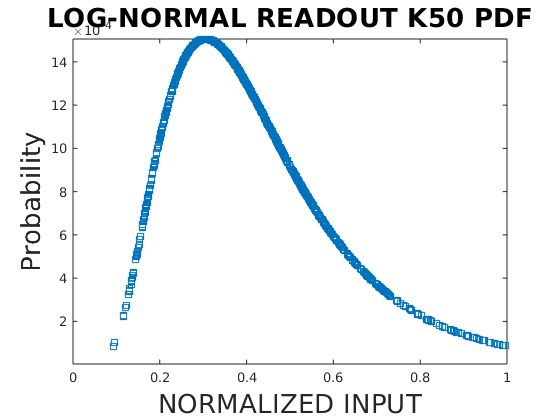

            

%==============================================
%  READOUT PROMOTER:
%==============================================
xmu = 0.5;
xs2 = (xmu*xr)^2;
%     %conversions from target to log-normal mean,variance:
    lnmu = log(xmu/sqrt(1 + xs2/(xmu*xmu)));
    lns2 = log(1 + xs2/(xmu*xmu));
    pd = makedist('Lognormal','mu',lnmu,'sigma',lns2);
    r = random(pd,rsamples,1); % generate numbers from the distribution to get its "center"
%     ixfp = linspace(min(r), max(r)); % to scale the graph
    yxfp = pdf(pd, r);%generate pdf for the "center" of the distribution
    yxfp = yxfp / sum(yxfp);%normalize to sum to 1            
    
    figure;
    plot(r, yxfp, 's');
    axis([0 1 -inf inf]);
    title({'LOG-NORMAL READOUT K50 PDF'}, 'FontSize', FS);
    xlabel('NORMALIZED INPUT', 'FontSize', FS); 
    ylabel('Probability', 'FontSize', FS);




%==============================================
%  CONVOLVED SIGNALS:
%==============================================
% r is the readout K50s, yxfp is its pdf
% hill is the 1st-stage ouptut, ylac is its pdf
    hedges = linspace(0,1,rsamples);%edges of histogram in [0,1]
    targetdist = zeros(1,length(hedges));%the histogram bins accumulator
    figure;
    for i=1:length(hill)%for each 2nd stage input signal
        hpow = (hill(i)./r) .* (hill(i)./r);
        hill2 = hpow./(1+hpow);%transformed output pdf per input hill(i)
%         plot(hill2, yxfp*ylac(i), 's'); hold on;
        [N, edges,bin] = histcounts(hill2, hedges);
        for j=1:length(hill2)%add weighted probability to each bin hit by output
            targetdist(bin(j)) =   targetdist(bin(j))+ yxfp(j)*ylac(i);
        end
        
    end

    
   m1 = sum(hill .* ylac)

m1 = 0.6571

   v1 = sum((hill-m1) .* (hill-m1) .* ylac)

v1 = 0.0203

   s1 = sqrt(v1)

s1 = 0.1424

   cv1 = s1/m1

cv1 = 0.2168

       m2 = sum(hedges .* targetdist)

m2 = 0.7410

       v2 = sum((hedges-m2) .* (hedges-m2) .* targetdist)

v2 = 0.0230

       s2 = sqrt(v2)

s2 = 0.1515

       cv2 = s2/m2

cv2 = 0.2045


%     plot(hill, ylac/max(ylac), 's');  hold on;
%     plot(hedges, targetdist/max(targetdist), 's'); 
    plot(hill, ylac, 's');  hold on;
    plot(hedges, targetdist, 's'); 
%     plot(m1*ones(1,100), linspace(0,1,100));
%     plot(m2*ones(1,100), linspace(0,1,100));

    %sample random points to thin data:
    ithin = round(length(targetdist)/4);
    ri = round(rand(1,ithin)*length(targetdist)); 
    xri=hill(ri);
    pri=ylac(ri)/sum(ylac(ri));
    mri=sum(xri.*pri)

mri = 0.6671

    vri=sum((xri-mri).*(xri-mri).*pri)

vri = 0.0219

    
   skew1 = sum((hill-m1) .* (hill-m1) .* (hill-m1) .* ylac)/(s1*s1*s1)

skew1 = -0.4760

   skew2 = sum((hedges-m2) .* (hedges-m2) .* (hedges-m2) .* targetdist)/(s2*s2*s2)

skew2 = -1.0357

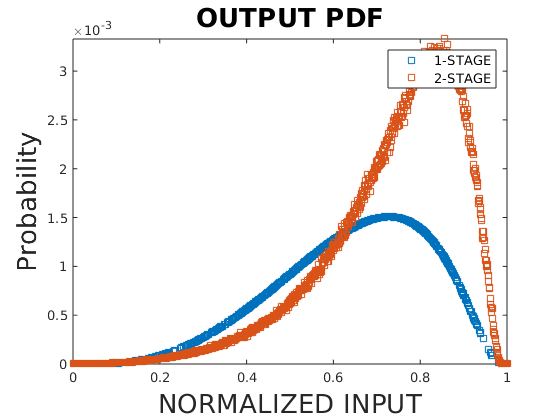

%     plot(xri, pri, 'cs');
    
    hold off;
    axis([0 1 -inf inf]);
    title({'OUTPUT PDF'}, 'FontSize', FS);
    xlabel('NORMALIZED INPUT', 'FontSize', FS); 
    ylabel('Probability', 'FontSize', FS);
    legend(['1-STAGE'; '2-STAGE'], 'FontSize', FS/2);

    
       
       
    % 
    return;
    
    

    figure;
    yyaxis left;
    plot(hill, ylac, 's');  hold on;
    ylabel('Scaled Frequency', 'FontSize', FS);
    yyaxis right;
    plot(hedges, targetdist, 's'); 
%     plot(m1*ones(1,100), linspace(0,1,100));
%     plot(m2*ones(1,100), linspace(0,1,100));
    
    
    hold off;
    axis([0 1 -inf inf]);
    title({'OUTPUT PDF'}, 'FontSize', FS);
    xlabel('NORMALIZED INPUT', 'FontSize', FS); 
    ylabel('Scaled Frequency', 'FontSize', FS);
    legend(['1-STAGE'; '2-STAGE'], 'FontSize', FS/2);
    
%        return;


    sortedData1 = sortrows([hill ylac]);
    figure;
%     yyaxis left;
    plot(sortedData1(:,1), ...
        cumsum((sortedData1(:,1)-m1) .* (sortedData1(:,1)-m1) .* sortedData1(:,2)), 's');  
    hold on;
%     ylabel('Scaled Frequency', 'FontSize', FS);
%     yyaxis right;
    plot(hedges, cumsum((hedges-m2) .* (hedges-m2) .* targetdist), 's'); 
%     plot(m1*ones(1,100), linspace(0,1,100));
%     plot(m2*ones(1,100), linspace(0,1,100));
    
    
    hold off;
    axis([0 1 -inf inf]);
    title({'CUMULATIVE VARIANCE'}, 'FontSize', FS);
    xlabel('NORMALIZED INPUT', 'FontSize', FS); 
%     ylabel('Scaled Frequency', 'FontSize', FS);
%     legend(['1-STAGE'; '2-STAGE'], 'FontSize', FS/2);
    
       return;
       
%     figure;
    xx=500;
    plot(hill2(1,:), yxfp*ylac(1), 's'); hold on;
    plot(hill2(xx,:), yxfp*ylac(xx), 's'); hold on;
    plot(hill2(end,:), yxfp*ylac(end), 's'); hold off;
    axis([0 1 -inf inf]);

%     plot(hill2(1), ylac)
% 
% 
% hillx = linspace(0,10,100);
% hillk = 0.5;
% % hilln = 2;
% hillpow = (hillx/hillk) .* (hillx/hillk);%n=2
% figure;
% plot(hillx, hillpow./(1 + hillpow));
return;


thisData = highResolutionDataVector;
polev = 4/3 * pi * 0.5*0.5*0.5;
lenv = pi*0.5*0.5;
% cellv = (thisData(:,1)-1)*lenv + polev;
cellv = (thisData(:,1))*lenv;
plot(thisData);
% plot(thisData(:,2));  
plot(thisData(:,2)./cellv./0.602);
    
xl = 2.1:0.1:4.5;
cellvpre = (xl-1)*lenv + polev;
cellvpost = (xl/2-1)*lenv + polev;

plot(xl, cellvpost*2./cellvpre);


clear all;

basePath = "~/Dropbox/xps/eQ/build/images/";

% LOAD FILE
% [file path] = uigetfile('~/Dropbox/xps/eQ/build/*.json', 'Open File');
% [file path] = uigetfile(sprintf("%s*.txt", basePath), 'Open File');

% get a dir path using UI interface
selpath = uigetdir(basePath);%
dinfo = dir(sprintf("%s/*.txt", selpath))
% determine how many files (of any type) are in this directory 
nfiles = length(dinfo);
myFiles = strings(1, nfiles);
fileCounter = 0;

thisExtension = '.txt';
% get file full name and determine if it is of correct type, add to list
for i = 1 : nfiles
  filename = fullfile(dinfo(i).folder, dinfo(i).name);
  [fp fn fe] = fileparts(filename);
  if strcmp(fe, thisExtension)
      display(dinfo(i).name);
      fileCounter = fileCounter + 1;
      myFiles(fileCounter) = filename;
  end
end
myFiles = myFiles(1:fileCounter);%trim the array to actual number of files

% we now have a list of valid file names 
%==========================================================================
%  SEQUENCE ALL .txt FILES IN FOLDER:
%==========================================================================
% formatSpec = '%f  %f';
formatSpec = '%f  %f  %f  %f';%space-separated data,valid for each data row
sizeA = [4 Inf];%each row in file is treated as a column vector when read-in
highResData = {};
for i = 1 : fileCounter
    fileID = fopen(myFiles(i),'r');
    A = fscanf(fileID,formatSpec,sizeA);
    fclose(fileID);    
    highResData{i} = A;
end

%
figure;
for i = 1 : fileCounter
    thisData = highResData{i};
    plot(thisData(1,:)); hold on;   
end
hold off;


figure;
for i = 1 : fileCounter
    thisData = highResData{i};
    plot(thisData(2,:)); hold on;   
end
hold off;


zx=linspace(1,60);
zn=2;
% zK=30;
zK=60;
zHbyKn = power(zx/zK, zn);
zHill = zHbyKn ./ (1+zHbyKn);

zr1=1:100;
zx2 = zHill(zr1)*100;
zK2=30;
zHbyKn2 = power(zx2/zK2, zn);
zHill2 = zHbyKn2 ./ (1+zHbyKn2);

plot(zx, zHill);  hold on;
plot(zx(zr1), zHill2);  hold off;
axis([-inf inf 0 1]);
semilogx(zx, zHill); axis([-inf inf 0 1]);
plot(zx, zHill); axis([-inf inf 0 1]);

